**ESM Final Notebook - Temperature and Evaporation in a Shallow Lake **

Sophia Sparks and Emily Tribby 

Video Walk-through Part 1: 

[https://youtu.be/bwtaIKjEIuc](https://youtu.be/bwtaIKjEIuc)

Video Walk-through Part 2: 

[https://youtu.be/ndTSZ0CIBfw](https://youtu.be/ndTSZ0CIBfw) 

**Introduction: **

    Understanding the seasonal variation in lake temperatures is useful in a variety of climate change and lake hydrology studies. Models of the thermal structure of lakes can also play an important role in more complex lake models that allow for evaporation and lake-level estimates (Hostetler & Bartlein, 1990). The thermal structures of many lakes show vertical stratification of their water masses, often in a seasonal pattern (Boehrer & Schultze, 2008). For example, shallow water bodies that are characterized by high turbidity levels absorb solar radiation within a relatively thin surface layer, which can result in stratification (Condie & Webster, 2002). Modeling thermal stratification is particularly important for these water bodies, as the process can limit the transfer of oxygen and other dissolved gasses through the water column and lead to anoxic conditions. Since the 1990s, Malheur Lake has been in a turbid state, which is characterized by a lack of submergent vegetation, high turbidity, and higphytoplankton biomass, meaning it is a useful example for stratification studies (Smith & Wood., 2023). The seasonal cycles of the temperature of a lake can be simulated by one-dimensional stratification models that account for the vertical processes that are most important in controlling lake heating (Wang et al., 2019). These physical processes include the surface energy balance (SEB), the absorption of incoming solar radiation, and turbulent mixing. 

    Stratification models are often categorized into two categories: mixed layer or integral models and eddy diffusion or differential models (Hostetler & Bartlein, 1990). These 1-dimensional models assume that the physical properties of lake water are horizontally uniform and only the heat transfer of lake water in the vertical direction is considered. (Wang et al., 2019). More sophisticated 1-D schemes, such as the Lagrange DYRESM model (Yeates, 2003), the E–ε SIMSTRAT turbulent closure model (Goudsmit et al., 2002), and the LAKE model (Stepanenko et al., 2005 & 2014), consider the turbulent motion of water for more accurate simulations. Many of these lake models accurately demonstrate the seasonal and diurnal cycles of surface temperatures, however show discrepancies between observed water temperatures and calculated water temperatures below the surface. Hostetler & Bartlein (1990) noted that no single category of model is the best for all applications, and therefore the selection of a model is best guided by the intended use to produce the most accurate estimates of lake temperatures. To simulate seasonal temperature variations in the Malheur Lake depth profile, a 1-dimensional thermal diffusion model with parameterized eddy diffusion in water proposed by Hostetler & Bartlein (1990) was deployed. 

**Equations: **

Modeling a lake's thermal structure involves various physical and chemical processes including radiative forces, turbulent mixing, evaporation and eddy diffusion. The net heat flux at the surface is controlled by the amount of solar radiation that the surface layer absorbs and the heat that is radiated out by the surface itself. Turbulent mixing involves the irregular flow of water. At a lake's surface, turbulence is driven by changes in wind and temperature. In stratified lakes, turbulent mixing promotes the movement of heat which would otherwise be suppressed by significant temperature differentials  (Cadwell et al., 1995). At the surface-atmosphere interface, changes in the saturation vapor pressure are dependent on ambient temperature. When there is adequate energy and a vapor pressure differential between these two mediums is present, evaporation will proceed. Eddy diffusion describes how a substance (heat) is dispersed through a fluid based on random fluctuations in velocity and direction (University of California San Diego). This interplay of radiative forces, turbulent mixing, evaporation, and eddy diffusion intricately shapes a lake's thermal structure.  

The lake of interest, Malheur lake, has a maximum depth of 4 meters. As a result, surface temperature can be estimated using a surface energy balance (SEB) based on solar irradiance and ambient temperature  (3). Ks is the net shortwave radiation at the water surface (W/m^2). Lds is the net long-wave radiation from the atmosphere in W/m^2 (11). It is defined by the shortwave surface albedo of the lake’s surface which is a function of the sun’s position (14) and the average cloud coverage (Henderson-Sellers 1986). Ld is the long wave radiation from the atmosphere defined by the Stefan-Boltzman Law wherein emissivity is determined by cloud coverage (Henderson-Sellers 1986) (21). Lu is the long-wave radiation from the lake surface (W/m^2) (24). Qe is the flux of latent heat, i.e, the flux of heat governing phase changes. Qh is the flux of sensible heat- the flux of heat responsible for raising or lowering temperature. It is defined by Qe and the Bowen ratio R, which is the ratio of sensible heat to latent heat flux.  Qe is defined by the density of evaporated water vapor (1 kg m^-3), latent heat of vaporization (Le) and E, evaporation. Evaporation is calculated with the current wind speed, vapor pressure differential, and N, an empirically determined mass transfer coefficient defined by (26). The saturation vapor pressure at the surface is determined by (27). The ambient vapor pressure is then determined by the difference between the wet and dry bulb temperature shown in 28 where eas is the saturation vapor pressure of the air at the wet bulb temperature and gamma is the psychrometric constant (Oke, 1987). 

In lakes which are deep or sufficiently turbid, there is little heat transfer between lake sediments and the bottom waters, thus a no-flux boundary can be assumed at depth. Although Malheur Lake is very shallow, it has high levels of suspended sediment concentrations, thus a no-flux bottom boundary was adopted (USGS) (4). 

The eddy diffusion coefficient is defined by (5), which is based on the model developed by Henderson-Sellers (1986). It modifies the neutral eddy diffusion coefficient by the horizontal current’s vertical profile (Henderson-Sellers (1986). Ws is the friction velocity, k is von karmon constant (0.4). P0 is the neutral value of the turbulent Prandtl number (1.0). ks is a parameter of the Ekman profile (where frictional forces are balanced with coriolis forces) which depends on the latitude of the lake of interest and the current wind speed (7). Ri is the gradient Richardson number, which modifies the neutral eddy diffusion coefficient to describe non-neutral conditions (Henderson-Sellers 1985). Ri is defined by (8) where N is the Brunt-Vaisala frequency which has been approximated to a constant 0.002 s^-1. 

Meteorological data including dry and wet bulb ambient temperature (Ta and Tw), atmospheric pressure (P), wind speed (U2), and cloud coverage (C) was acquired from USGS. Solar irradiance (Kd) data was acquired from the University of Oregon Solar Radiation Laboratory. Daily averages for 2022 were calculated from the hourly data files for each parameter. 

    *Assumptions*

In this model, time steps (dt) and spatial grid spaces (dz) were chosen to both be 1, so as to align with our meteorological data. A sufficiently turbid lake was assumed such that a no-flux boundary could be implemented at the bottom. For the initial simulation, the surface boundary condition outlined in Hostetler (1990) was ignored in favor of a simpler approximation by a cubic spline interpolation of observed data obtained from USGS. For some of our simulations, we assumed negative temperatures to be equal to 0, to account for ice formation. The temperature at the bottom was defined to be 2 deg C, based on trends seen in other shallow lakes at similar latitudes. The initial condition, temperature for all z at time zero, was determined by the observed USGS dataThe Brunt-Vaisala frequency, and the density of freshwater were assumed to be constant values, 0.002 s^-1  and 1 kg *m^-3 , respectively. 

    *Relevant Equations*

**Governing Equation **(1)


$$\frac{\delta T}{\delta t}=\frac{1}{A\left(z\right)}\frac{1}{\delta z}\left\lbrace A\left(z\right)\left\lbrack k_m +K\left(z,t\right)\right\rbrack \frac{\delta T}{\delta z}\right\rbrace +\frac{1}{A\left(z\right)}\frac{1}{C_w }\frac{\delta \left\lbrack \phi A\left(z\right)\right\rbrack }{\delta z}$$


T  is water temperature (˚C), t is time (day), z is depth from the surface (m), A(z) is lake area at depth z (m^2), Km is the molecular diffusion of water (m^2 d^-I), K(z,t) is eddy diffusivity (m^2 d^-I), Cw is the volumetric heat capacity of water (J m^-3 ˚C^-1), and ß  is a heat source term (W m^-2). The heat source term [Dake and Harleman, 1969] accounts for subsurface heating by the absorption of penetrating solar radiation, in accordance with Beer's law

**Heat Source Term** (2)


$$\phi =\left(1-\beta \right)K^* e^{-\left(\eta z\right)}$$


**Surface Boundary Condition** (3)


$$\left\lbrack k_m +K\left(z,t\right)\right\rbrack$$

$$\frac{\delta T}{\delta t}=K^* +L_d^* -L_u \pm Q_e \pm Q_h$$
 

**Bottom Boundary Condition **(4)


$$\left\lbrack k_m +K\left(z,t\right)\right\rbrack$$

$$\frac{\delta T}{\delta t}=0$$


**Eddy Diffusion Coefficient** (5) 


$$K\left(z\right)=\left(\frac{kw^* z}{P_0 }\right)e^{\left(-k*z\right)} {\left(1+37Ri^2 \right)}^{-1}$$


**The Surface Value of the Friction Velocity** (6) 

w* = 1.2 x ${10}^{-3}$$U_2$

**The Wind Speed 2m Above the Water Surface** (7) 

$k^*$ = 6.6(sin $\phi {\left.\right)}^{1/2}$$U_2^{-1\ldotp 84}$

**The Latitude of the Lake Being Modeled** (8)

Ri = $\frac{-1+\lbrace 1+40N^2 k^2 z^2 /\lbrack w^{*2} \;\exp \;\left(-2k*z\right)\rbrack \rbrace^{1/2} }{20}$

**The Brunt-Vaisala Frequency** (9) 

N = $\lbrack -g/\rho \left(\delta \rho /\delta z\right)\rbrack^{1/2}$

**Density of Fresh Water** (10) 


$$\rho =\left(1-1\ldotp 9549\;x\;{10}^{-5} |T_k -277|^{1\ldotp 68} \right){10}^3$$


**Net Shortwave Radiation at the Lake Surface** (11)


$$K^* =K_d \left(1-A_s \right)$$


**Incoming Global Shortwave Radiation** (12 & 13) 


$$A_{\textrm{sa}} =\left({\alpha t}_d /2H\pi \right)F$$



$$a=0\ldotp 02+0\ldotp 01\left(0\ldotp 5-C\right)\lbrace 1\ldotp 0-\sin \lbrack \pi \left(1-81\right)/183\rbrack \rbrace$$


**The Fraction of Sky Obscured by Cloud **(14)

$\cos \left(H\right)$ = -tan ($\left.\theta \right)\;\tan \;\left(\delta \right)$

**Solar Declination** (15)


$$\delta =-23\ldotp 4\;\cos \left\lbrack 360\frac{\left(I+10\right)}{365}\right\rbrack$$


**Intergration Factor **(16 - 19)


$$\begin{array}{l}
F=2{\left(b^2 -c^2 \right)}^{-\frac{1}{2}} \;\tan^{-1} \left(B^{\frac{1}{2}} \right)\;\;\;\;\;b^2 -c^2 >0\\
F=2{\left(-b-c^2 \right)}^{-\frac{1}{2}} \;\ln \left\lbrace \frac{\left\lbrack 1+\left(-B^{\frac{1}{2}} \right)\right\rbrack }{\left\lbrack 1-\left(-B^{\frac{1}{2}} \right)\right\rbrack }\right\rbrace \;\;\;\;\;b^2 -c^2 <0
\end{array}$$


    
$$\begin{array}{l}
b=a+\sin \left(\theta \right)\sin \left(\delta \right)\\
c=\cos \left(\theta \right)\cos \left(\delta \right)\\
B=\left\lbrack \frac{b-c}{b+c}\right\rbrack \tan^2 \left(\frac{\pi H}{2t_d }\right)
\end{array}$$


**Long-wave Radiation from the Atmosphere **(20)


$$L_d =\varepsilon_a \sigma {\left(T_a +273\right)}^4$$


**Emissivity of the Atmosphere** (21 & 22) 


$$\begin{array}{l}
\varepsilon_a =0\ldotp 84-\left(0\ldotp 1-9\ldotp 973\times {10}^{-6} e_a \right)\left(1-C\right)+3\ldotp 491\times {10}^{-6} e_a \;\;\;\;\;\;\;\;\;\;\;1-C\ge 0\ldotp 4\\
\varepsilon_a =0\ldotp 87-\left(0\ldotp 175-29\ldotp 92\times {10}^{-6} e_a \right)\left(1-C\right)+2\ldotp 6933\times {10}^{-5} e_a \;\;\;\;\;\;\;\;\;\;\;1-C<0\ldotp 4
\end{array}$$


**Long-wave radiation from the atmosphere **(23) 


$$L_d^* =\left(1-A_1 \right)L_d$$


    
$$A_1 =0\ldotp 3$$


**Longwave radiation of the lake surface **(24)


$$L_u =\varepsilon \sigma {\left(T_s +273\right)}^4$$


    $\varepsilon$ = 0.97 

**Evaporation** (25) 


$$E=NU_2 \left(e_0 -e_a \right)$$


**Mass Transfer Coefficient** (26) 


$$N=0\ldotp 029A^{-0\ldotp 05}$$


**Saturation Vapor Pressure at the Lake Surface** (27) 


$$e_0 =101\ldotp 1\ldotp 325\;\exp \left(13\ldotp 3185t_k -1\ldotp 9760t_k^2 -0\ldotp 6445t_k^3 -0\ldotp 1229t_k^4 \right.$$


    
$$t_k =1-\left\lbrack 373\ldotp 15/\left(T_s +273\right)\right\rbrack$$


**Ambient Vapor Pressure of the air **(28)


$$e_a =e_a^* -\gamma \left(T_a -T_w \right)$$


**Flux of latent heat **(29)


$$Q_e =\rho L_e E$$


**Latent Heat of Vaporization** (30)


$$L_e \left(T_s \right)=1\ldotp 91846\times {10}^6 {\left\lbrack \left(\textrm{Ts}+273\right)/\left(\textrm{Ts}+329\ldotp 09\right)\right\rbrack }^2$$


**Flux of Sensible Heat** (31) 


$$Q_h ={\textrm{RQ}}_e$$


**Bowen ratio** (32)


$$R=\gamma \left(T_s -T_a \right)/\left(e_0 -e_a \right)$$


**Numerical Models **

To model the thermal structure of Malheur Lake, an FTCS method with Neumann boundary conditions was implemented. This method employs a forward euler approximation in time and centered difference scheme in space. Using boundary and initial conditions, an explicit equation for the next time step can be evaluated. FTCS, although conditionally stable for Cd = D*(dt/dx^2)<½., is less computationally intense than other methods, which is why it was chosen for this scenario. 

The Crank-Nicholson method stands out for its unconditional stability, offering reliability in solving equations. However, its implicit nature makes its implementation more complex compared to other methods. This technique utilizes a finite difference approach to numerically solve partial differential equations (PDEs). The same boundary conditions, initial values, and parameters as in our FTCS scheme were used. 

**Results **

6 simulations were run to compare the results between the two numerical methods, a constant vs depth-dependent diffusion coefficient (Cd), three light extinction coefficient (n) values, and adjustments of the surface and bottom boundary conditions.

Simulation 2 and simulation 6 highlight the results using the FTCS and the Crank Nicholoson Method, respectively. From these two simulations, it is evident that there are differences in the thermal structure that result from their implementation. Both models do show warmer temperatures throughout the water column in the fall that are a delayed response from summertime heating

Simulation 1 and simulation 2 highlight the results using a constant Cd and a Cd that depends on depth, respectively. Diffusion from the surface was more rapid in simulation 2 when using equation 5 to accurately describe eddy diffusion.

Simulation 4 highlights the results using two light extinction coefficient (n) values, in addition to the provided value of 1.2 1/m. The changing of these values simulated changes in subsurface heating by the absorption of penetrating solar radiation through equation 3. Decreasing the value increased temperatures throughout the water column while increasing the value generally decreased temperatures throughout the water column.

Simulation 3 highlights the results changing the surface and bottom boundary conditions. The surface boundary in simulation 3 incorporated the energy balance at the surface using daily meteorological conditions with the Neuman boundary approximated by cubic spline interpolation of observed surface temperatures in 2022. Consequently, the daily fluctuations in these meteorological conditions can be observed in the water temperature contours when compared to the simplified surface boundary conditions used in simulation 1 and 2. Instead of the bottom boundary being set to 2 ˚C warmer than the surface temperature on Jan. 1, 2022, the condition in simulation 3 was altered to a set temperature of 2 ˚C to more accurately reflect realistic conditions for the physical properties of this lake. The result of both boundary changes was a much more realistic temperature profile and range.

The model results were compared to the thermal profiles of Bartosiewicz et al. (2019) to validate their potential accuracy. The study utilized "FLake" which is a 1D model that calculates the evolution of the horizontally averaged temperature profile in the water column of lakes.

 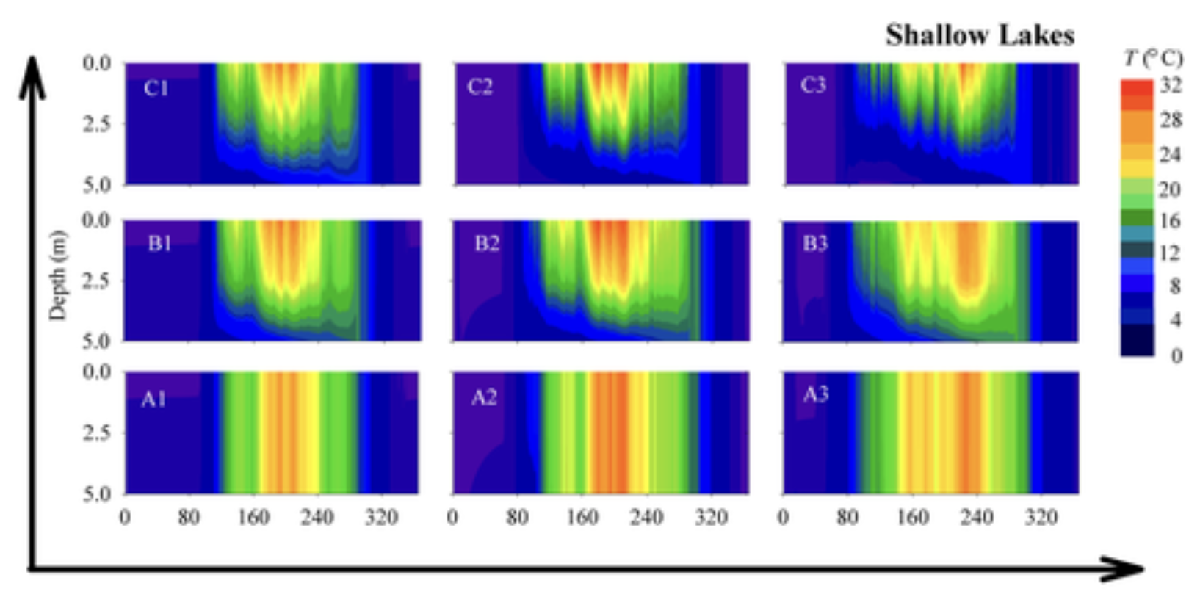

(Bartosiewicz et al., 2019)

   These plots show temperatures and stratification of shallow lakes as a function of warming and transparency loss over an annual cycle. The letters represent changes in the light extinction coefficient, and therefore transparency from (A) “very clear” to (B) “clear” lake to (C) “turbid”. The numbers represent changes in average temperature due to climate change, with number 1 most accurately reflecting surface temperature conditions of Malheur Lake. The results demonstrate a similar pattern of stratification and temperature diffusion from season surface changes. The changes in turbidity are also reflected in alterations of overall water temperature throughout the water column, however, the contours do not demonstrate the delayed response in warming to Summer heating as seen in the results of this model.

    The thermal profile of shallow lakes has been modeled by many additional methods. Models generally display synchronicity between surface temperatures and seasonal variations. Depending on turbidity, these lakes transfer heat from the surface differently. In highly turbid conditions, little heat can be transferred to lower depths, which results in significant stratifications. Known models often choose smaller increments for their spatial parameters (z). This results in a more detailed profile than depicted in our results. At this latitude, most models account for ice formation by altering model processes. For ease of computation, these modifications were simplified in our simulations, which caused our results to vary from known models. Excluding temperatures influenced by the simplification of ice coverage, the temperature ranges for our simulations align well with observed data for this lake.

    	The results from our model indicate that fluctuations in meteorological parameters greatly impact the surface temperature of a lake, which in turn impacts the thermal structure as a whole. Eddy diffusion greatly impacts the movement of heat throughout the lake. The extent to which heat diffuses is largely dependent on the distance from the lake’s surface. Therefore, it is important to utilize a depth-dependent diffusivity to accurately model the thermal structure. The light extinction coefficient, n, measures the clarity of water. A low n would indicate very clear waters whereas a high n would suggest high turbidity. As previously mentioned, turbidity influences the amount of radiation that can affect subsurface layers. Our results depict this phenomenon and suggest that there is a delayed response to this perturbation.

    Because this lake is at a relatively high latitude, it experiences ice coverage during the winter months. This model could be improved by accounting for these conditions. Hostetler and Bartlein (1990) achieve this by altering the surface boundary condition when ice is present, i.e., when the surface temperatures are below 1 degree Celsius. A more accurate bottom boundary would also improve this model. Initially, a bottom boundary which was 2 deg higher than the surface temperature was implemented. Because our model started in January; however, these values were excessively low for the warmer months. Our second approach, which used a bottom temperature of 2 degrees Celsius, was a more physically realistic boundary, but nevertheless, it was not truly representative of what one would expect. 

**Simulations: **

Defining constants: 

qasazA=[6e8, 6e7, 5e6, 5e5, 5e4]; %area in m^2 for depths 0m-4m 
Beta=0.4; %proportion of shortwave radiation that is absorbed in the surface layer (40%)
n=1.2; %light extiction coefficient for water (m^-1) 
theta=deg2rad(47.3371); %latitude (deg N) 
sig= 5.67E-8; %stepfan boltzman constant (W/m^2K^4) 
td= 86400; %number of seconds in a day
km=2.0204*1E-9*td;  %molecular diffusion of water (m^2d^-1) 
A1= 0.3; %longwave albedo of the lake surface 
Rmw=0.622; %ratio molecular weight of water vapor/dry air = 0.622.
lambda= 2.45; %latent heat of water vaporization, [MJ kg−1]
Cp= 1.005/1000; %specific heat of air at contsant pressure (MJ/kg*K)
k= 0.4; %Von Karmon's constant 
P0= 1;%P0 is the neutral value of the turbulent Prandtl number 
Akm=323.3; %surface area of lake (km^2) 
N= 0.029*Akm^-0.05; %N empiracally determined mass transfer coefficient (mm s m^-1 kPa^-1) (26)
g=9.8; %m/s^2 acceleration due to gravity 
esp= 0.97; % emissivity
rhoe=1; %density of the evaporated water vapor(kg/m^3)
Cw=4184; %J/kgC
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 

Loading Meterological Data from 2022: 

data= readmatrix("met_data_2022_.csv");
data(:,1)=[];
Ta=data(:,1); %temperature dry bulb (deg C)
Tw=data(:,2); %temperature wet bulb (deg C)
U2= data(:,3)/2.237; %windspeed in mph-> meters/s
C=data(:,4);% cloud coverage (in tenths) 
Kd= data(:,5)/2400; %Solar irradiance data (watt hour /m^2/day )CONVERT TO W/m^2)
P=data(:,6); %pressure kpa

**Simulation 1**

Conditions: 

        Numerical Method: FTCS Method 

        Diffusion Coefficient = constant (Cd = 0.01) 

        Light Extinction Coefficeint = provided (n = 1.2) 

        Surface Boundary Condition: neuman boundary approximated by cubic spline interpolation of observed 2022 data

        Bottom Boundary Condition: no-flux neuman boundary, 2 degrees warmer than surface temperature on Jan. 1 2022 

This simulation used a constant value of 0.1 for Cd. Surface temperatures are warmest during the summer months, as they are synchronized with seasonal variations in this model. The heat is localized in the surface layer, but some diffusion is seen throughout the depth profile. Temperatures range from -25 deg C to 15 deg C. This temperature range is not physically reasonable, as ice would form at temperatures below zero. 

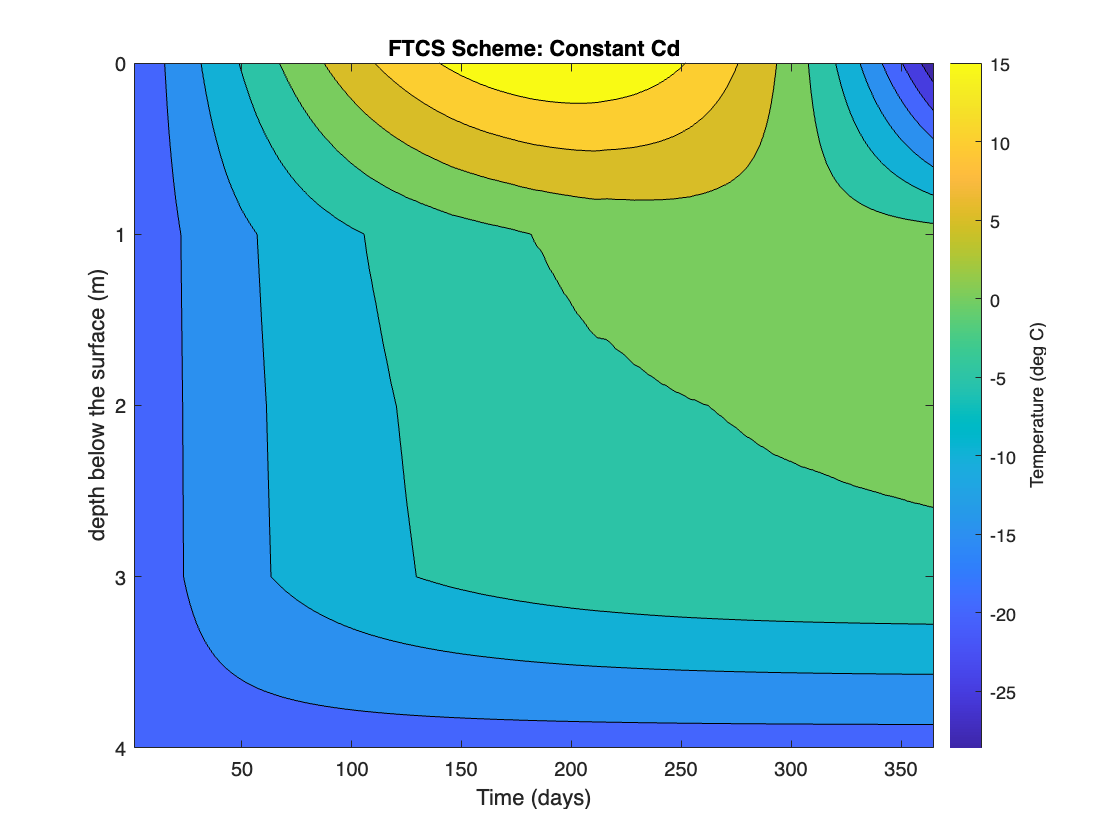

%preallocation 
I=linspace(1,365,365); % julian day 
t= I; %time in julian days 
dz = 1;%meters 
dt = 1; %days 

z=0:dz:4; %depth in meters 
nt=length(t);
nz=5;%length(z);
T=nan.*ones(nz,nt);
Tbound=nan.*ones(nz-2,nt);
S=nan.*ones(nz,nt);
phi = nan.*ones(1,nt);
K = nan.*ones(nz,1);

%set "source" term 
    for i = 1: width(S)
        S(:,i)= 1./(A*Cw);
    end 
    S(1,1) = 0; 
%set surface boundary condition 
    for i= 1: nt
        Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
    end 

%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

for i=1:nt-1
    %dependant on U2, I, Ta, Tw,C
    Ts=surftemp(I(i));
    a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
    deltadeg=-23.4*cos(360*(I(i) + 10)/365);
    delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
    cos_H=-tan(theta)*tan(delta);
    H=acos(cos_H);%half-day length (units?) (14)  
    b = a + sin(theta)*sin(delta); %(17)
    c=cos(theta)*cos(delta);%(18)
    B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)

    if ((b^2) -(c^2)) > 0 %16
        F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
    else 
        F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
    end 
    As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
    Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
    
    ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
    ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84; % a  latitudinally dependent parameter of the Ekman profile, (7) 
    Tk = Ts+273;%temperature of surface in kelvin 
    rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
    
    tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
    tk2= 1-(375.15/(Tw(i)+273));
    e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
    eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
    gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
    ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
    
    if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
        esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
    else 
        esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
    end 

    
    for m=2:nz-1
        Ri= richnum(Nbv, k,ws,z(m)); %richardson number 
        Cd = 0.01; 
        phi(i)= (1-Beta)*Ks*exp(-n*z(m))*(24*3600); % heat source term in (W/m^2) Beer's Law (2)-> J/m^2 
        S(m,i) = S(m,i)*phi(i)*(A(m-1)-A(m))/(dz*rhof); 
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end  
end
T_inverted = flipud(T);%invert so that the top is the surface 
figure()
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("FTCS Scheme: Constant Cd")

**Simulation 2 **

Conditions:    

        Numerical Method: FTCS Method 

        Diffusion Coefficient = depth-dependent 

        Light Extinction Coefficeint = provided (n = 1.2) 

        Surface Boundary Condition: neuman boundary approximated by cubic spline interpolation of observed 2022 data

        Bottom Boundary Condition: no-flux neuman boundary, 2 degrees warmer than surface temperature on Jan. 1 2022 

To account for eddy diffusion, a spatially dependent Cd was implemented. All other conditions were the same as Simulation 1. Diffusion from the surface is more rapid in this simulation, due to the spatial dependency of Cd. As a result, temperatures at depths below the surface are generally cooler than those of Simulation 1. 

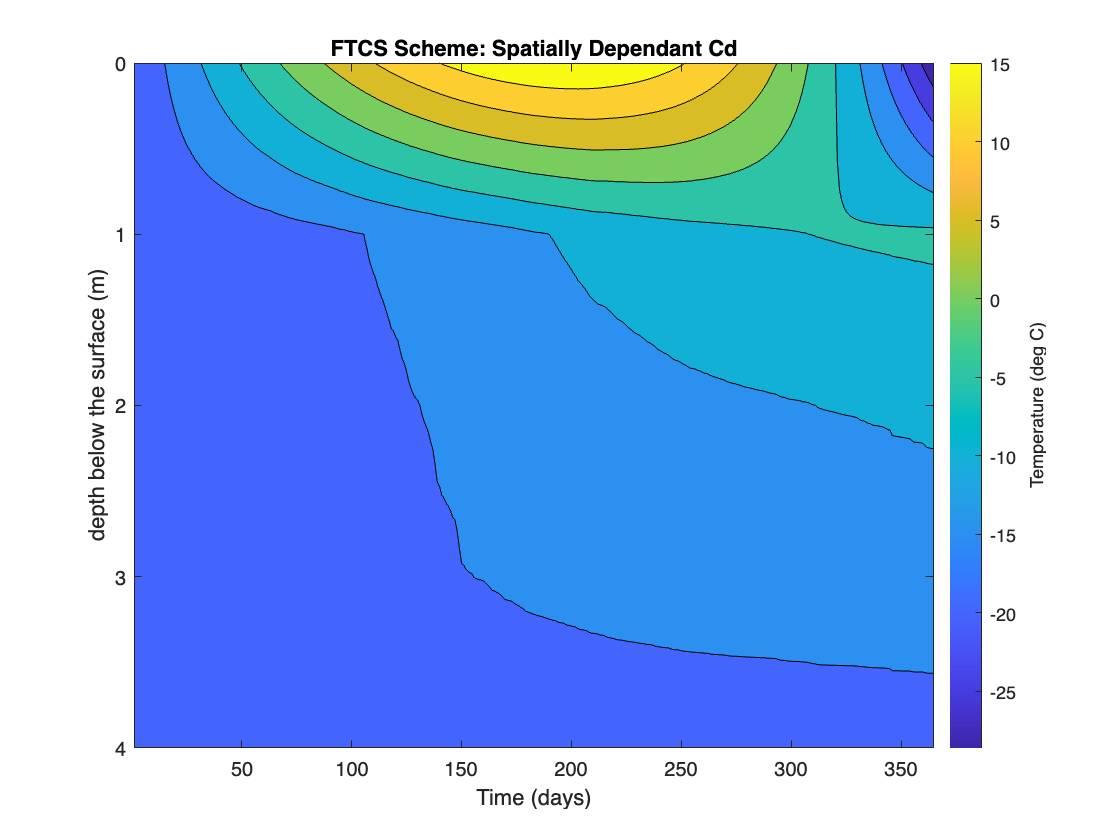

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 

%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));
end 

%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

for i=1:nt-1
%dependant on U2, I, Ta, Tw,C
Ts=surftemp(I(i));

a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
deltadeg=-23.4*cos(360*(I(i) + 10)/365);
delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
cos_H=-tan(theta)*tan(delta);
H=acos(cos_H);%half-day length (units?) (14)  
b = a + sin(theta)*sin(delta); %(17)
c=cos(theta)*cos(delta);%(18)
B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)

if ((b^2) -(c^2)) > 0 %16
    F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
else 
    F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
end 
As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 

ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84; % a  latitudinally dependent parameter of the Ekman profile, (7) 
Tk = Ts+273;%temperature of surface in kelvin 
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 

tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
tk2= 1-(375.15/(Tw(i)+273));
e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air

if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
    esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
else 
    esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
end 

Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
Le=1.91846E6*((Ts +273)/(Ts +329.09))^2; %latent hear fo vaporization (MJ kg^-1) 
E= N*U2(i)*(e0-ea); %evaporation (mm) 
Qe= rhoe*Le*E*(277.7778/1000)*24; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
Qh= R*Qe; % flux of sensible heat (31)

    for m=2:nz-1
        Ri= richnum(Nbv,k,ws,z(m)); %richardson number 
        K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
        Cd =  K(m)*dt/dz^2;
        phi(i)= (1-Beta)*Ks*exp(-n*z(m))*24*3600; % heat source term in (W/m^2) Beer's Law (2)--> J/m^2 
        S(m,i) = S(m,i)*(phi(i)*(A(m-1)-A(m))/(dz*rhof));
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end 

end

T_inverted = flipud(T);%invert so that the top is the surface 
figure()
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("FTCS Scheme: Spatially Dependant Cd")

**Simulation 3**

 Conditions: 

        Numerical Method: FTCS Method 

        Diffusion Coefficient = depth-dependent 

        Light Extinction Coefficeint = provided (n = 1.2) 

        Surface Boundary Condition: Neuman boundary based on energy balance at surface using daily meterological conditions  

        Bottom Boundary Condition: no-flux neuman boundary, set temperature of 2 ˚C 

In simulation 3, the boundary conditions at the surface and bottom were changed to reflect more accurate physical processes. At the surface, temperatures are controlled by the daily meteorological parameters that were acquired for this site. The boundary condition accounts for the energy balance at the surface described by equation 3. Consequently, the daily fluctuations in these meteorological conditions can be observed in the water temperature contours, most notably during the warmest months of the year. The bottom boundary was altered to a set temperature of 2 deg C to more accurately reflect realistic conditions for the physical properties of this lake. As noted in our previous simulations, temperatures were outside of a physically reasonable range. The observed surface temperature data from USGS was only reported from April to November. The assumption was made that this was a result of ice coverage during the winter months. Therefore, the cubic spline interpolation was least accurate for those winter months, which is why large negative numbers were observed in the previous simulations. To account for this error all negative temperatures were set to zero degrees celsius. The result was a much more realistic temperature profile and range. 

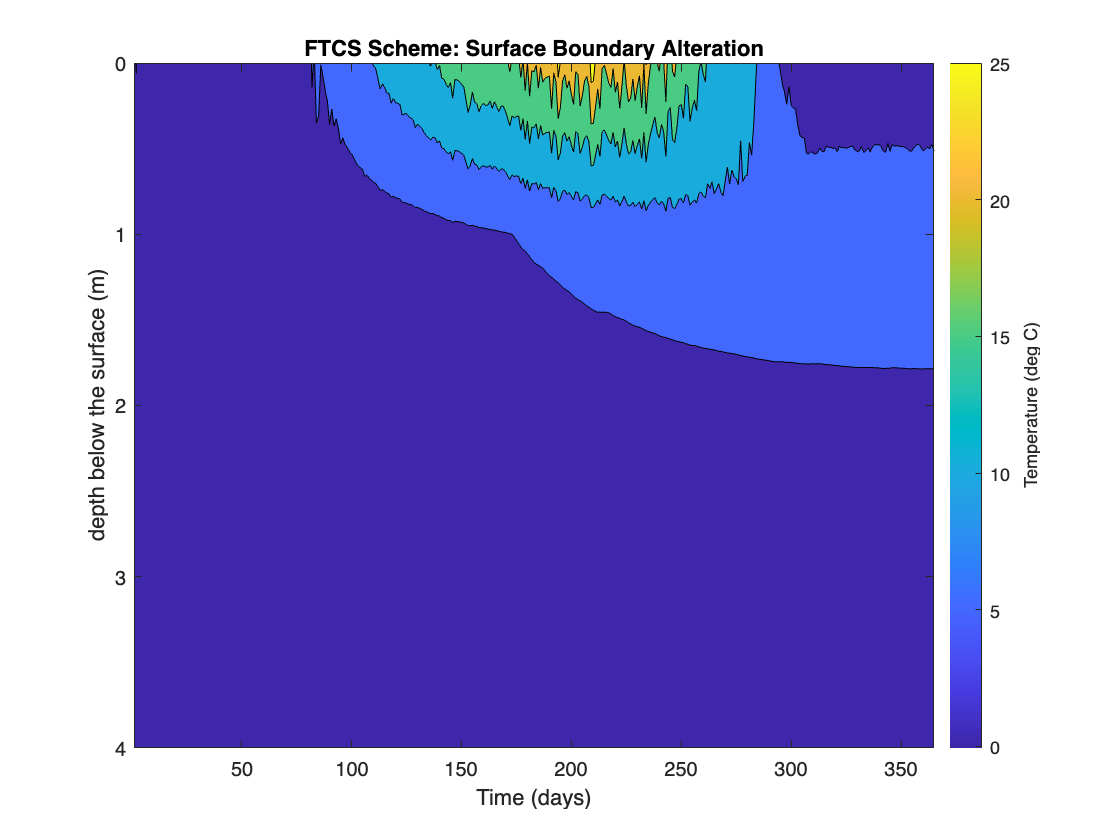

%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 

%set surface boundary condition 
for i= 1: nt
    Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
    if Tbound(1,i)<0
        Tbound(1,i)=0;
    end 
end 

%set bottom boundary 
Tbound(end, :)= 2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

for i=1:nt-1
%dependant on U2, I, Ta, Tw,C
Ts=surftemp(I(i));
    if Ts<0
        Ts=0;
    end 
a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
deltadeg=-23.4*cos(360*(I(i) + 10)/365);
delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
cos_H=-tan(theta)*tan(delta);
H=acos(cos_H);%half-day length (units?) (14)  
b = a + sin(theta)*sin(delta); %(17)
c=cos(theta)*cos(delta);%(18)
B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
    if ((b^2) -(c^2)) > 0 %16
        F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
    else 
        F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
    end 
As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)

Tk = Ts+273;%temperature of surface in kelvin 
rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 

tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
tk2= 1-(375.15/(Tw(i)+273));
e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
    if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
        esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
    else 
        esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
    end 
%Energy Balance Parameters to solve surface BC 
Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
Le=1.91846E6*((Ts +273)/(Ts +329.09))^(2); %latent hear fo vaporization (MJ kg^-1) 
E= N*U2(i)*(eas-ea)/1000; %evaporation (mm) -> meters 
Qe= rhoe*Le*E; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
Qh= R*Qe; % flux of sensible heat (31)
    for m=2:nz-1
        Ri= richnum(Nbv, k,ws,z(m)); %richardson number 
        K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
        T(1,i)= T(1,i) + ((Ks+Lds-Lu+Qe+Qh)*1E6/(rhof*(A(m)*Cw)))/(K(m));
        Cd = K(m)*dt/dz^2;
        phi(i)= (1-Beta)*Ks*exp(-n*z(m))*24*3600; % heat source term in (W/m^2) Beer's Law (2)
        S(m,i) = S(m,i)*phi(i)*(A(m-1)-A(m))/(dz*rhof);
        T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
        T(end,:) = T(end,1);
    end 
end
T_inverted = flipud(T);%invert so that the top is the surface 
figure()
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("FTCS Scheme: Surface Boundary Alteration")

**Simulation 4**

 Conditions: 

        Numerical Method: FTCS Method 

        Diffusion Coefficient: depth-dependent 

        Light Extinction Coefficeint: n = 0.5, 1.2, and 3 

        Surface Boundary Condition: Neuman boundary based on energy balance at surface using daily meterological conditions  

        Bottom Boundary Condition: no-flux neuman boundary, set temperature of 2 ˚C 

Altering the light extinction coefficient from the provided value of n = 1.2 1/m, simulates changes in the lake's turbidity. Decreasing the n to 0.5, decreases the turbidity and increases the visibility. The increase in visbility allow more solar radiation to penetrate, and thus increases subsurface heating. This is demonstarted in the first temperature contour plot with the warmer temperatures of in the water coloumn following the period of the year with the highest solar radiation amounts. Increasing the n to 3 has the opposite effect and allows less solar radiation to penetrate, thus decreasing subsurface heating. This is demonstarted in the third temperature contour plot with consistently colder temperature throughout the water column.

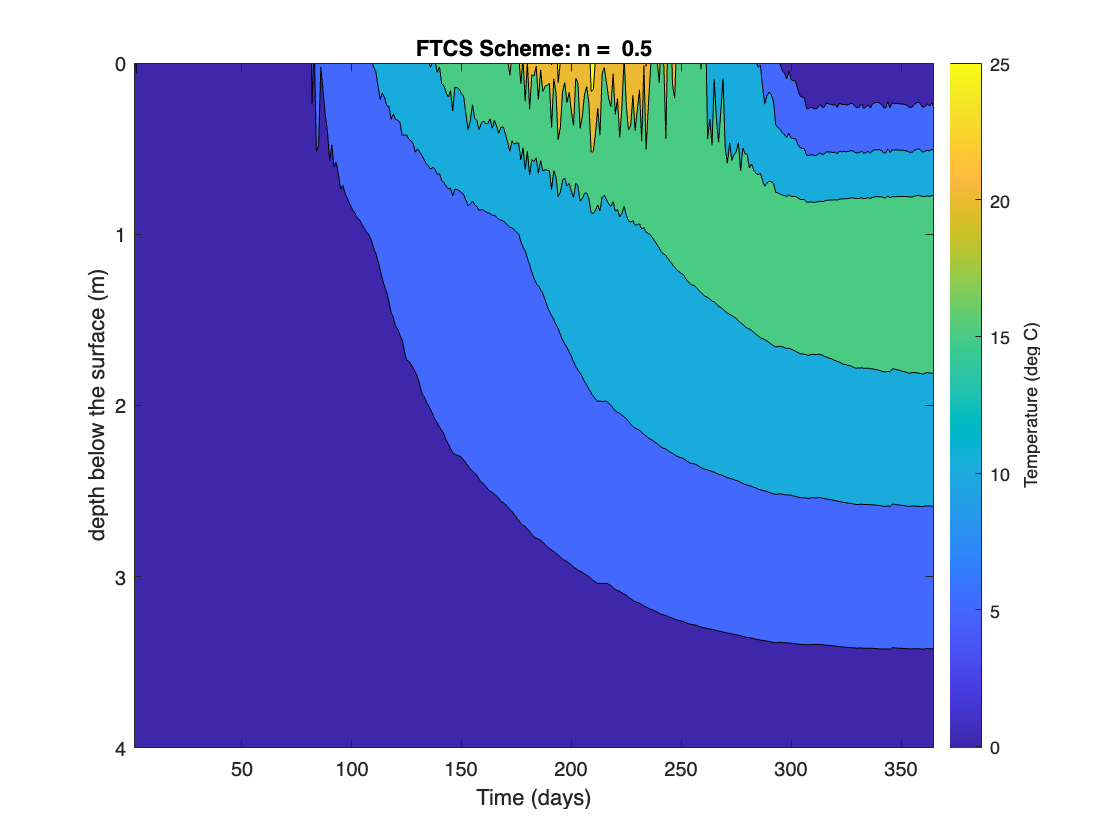

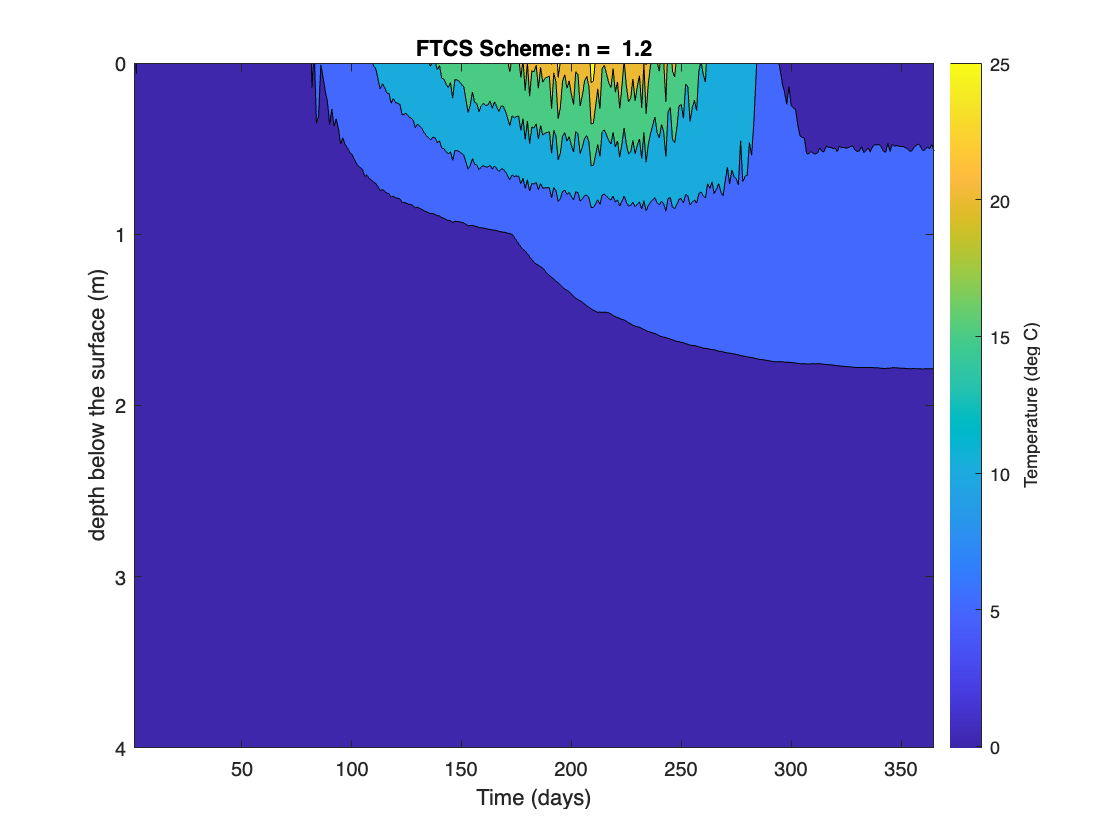

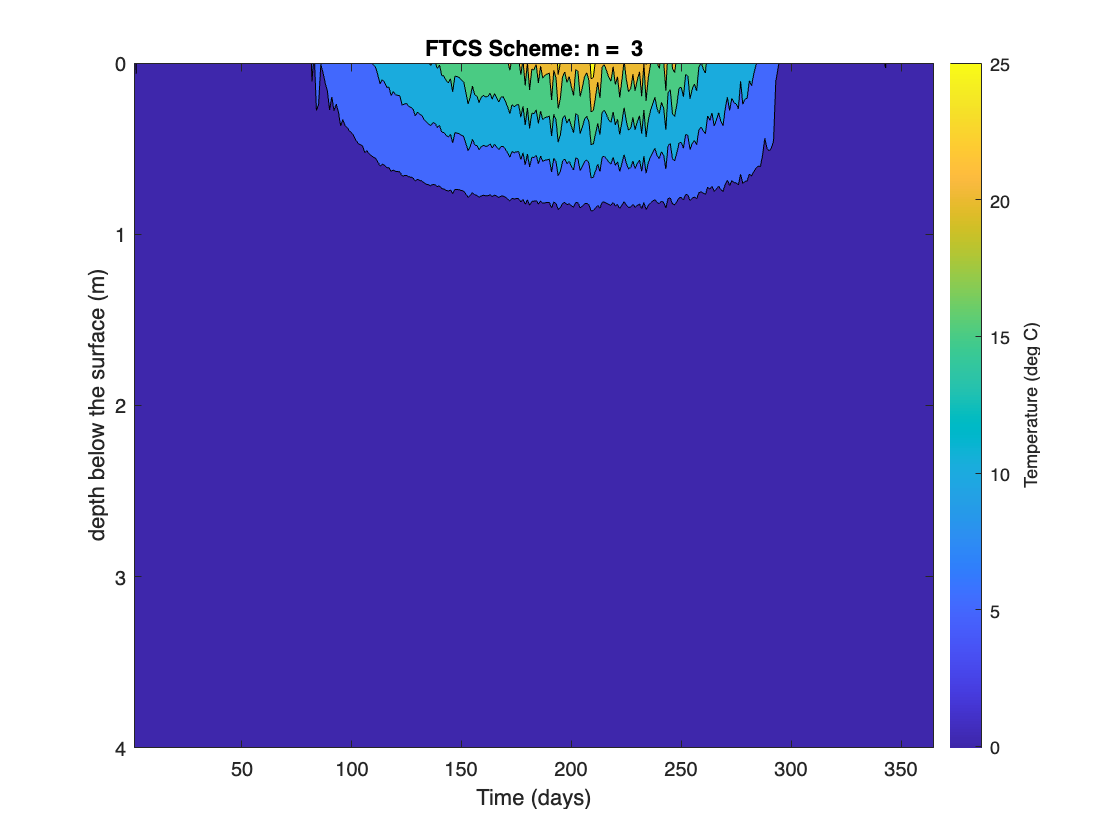

ns = [0.5,1.2,3];
for x = 1:length(ns) 
    n = ns(x);
    %set "source" term 
    for i = 1: width(S)
        S(:,i)= 1./(A*Cw);
    end 
    S(1,1) = 0; 
    
    %set surface boundary condition 
    for i= 1: nt
        Tbound(1,i)=surftemp(I(i));%neuman boundary aprroximated by cubic spline interpolation of observed data
        if Tbound(1,i)<0
            Tbound(1,i)=0;
        end 
    end 
    
    %set bottom boundary 
    Tbound(end, :)= 2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
    %set intial condition (T0 for all z)
    T(1,:)=Tbound(1,:);  
    T(end,1)= Tbound(end,1); 
    T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing
    
    for i=1:nt-1
    %dependant on U2, I, Ta, Tw,C
    Ts=surftemp(I(i));
        if Ts<0
            Ts=0;
        end 
    a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
    deltadeg=-23.4*cos(360*(I(i) + 10)/365);
    delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
    cos_H=-tan(theta)*tan(delta);
    H=acos(cos_H);%half-day length (units?) (14)  
    b = a + sin(theta)*sin(delta); %(17)
    c=cos(theta)*cos(delta);%(18)
    B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
        if ((b^2) -(c^2)) > 0 %16
            F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
        else 
            F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
        end 
    As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
    
    Tk = Ts+273;%temperature of surface in kelvin 
    rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
    Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 
    
    tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
    tk2= 1-(375.15/(Tw(i)+273));
    e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
    eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
    gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
    ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
        if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
            esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
        else 
            esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
        end 
    %Energy Balance Parameters to solve surface BC 
    Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
    ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
    ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
    Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
    Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
    Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
    Le=1.91846E6*((Ts +273)/(Ts +329.09))^(2); %latent hear fo vaporization (MJ kg^-1) 
    E= N*U2(i)*(eas-ea)/1000; %evaporation (mm) -> meters 
    Qe= rhoe*Le*E; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
    R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
    Qh= R*Qe; % flux of sensible heat (31)
        for m=2:nz-1
            Ri= richnum(Nbv, k,ws,z(m)); %richardson number 
            K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
            T(1,i)= T(1,i) + ((Ks+Lds-Lu+Qe+Qh)*1E6/(rhof*(A(m)*Cw)))/(K(m));
            Cd = K(m)*dt/dz^2;
            phi(i)= (1-Beta)*Ks*exp(-n*z(m))*24*3600; % heat source term in (W/m^2) Beer's Law (2)
            S(m,i) = S(m,i)*phi(i)*(A(m-1)-A(m))/(dz*rhof);
            T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
            T(end,:) = T(end,1);
        end 
    end
    T_inverted = flipud(T);%invert so that the top is the surface 
    figure()
    % Create the contour plot with the inverted depth axis
    contourf(T_inverted)
    % Set the depth values as y-axis tick labels
    depth_labels = string(z);  % Assuming 'z' contains your depth values
    depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
    yticks(1:length(z))  % Set the number of ticks to match the depth values
    yticklabels(depth_labels)  % Set the depth values as tick labels
    ylabel("depth below the surface (m)")
    xlabel("Time (days)")
    cb=colorbar;
    ylabel(cb, 'Temperature (deg C)')
    title("FTCS Scheme: n =  " + string(n))
end 

**Simulation 5**

Conditions:   

    Numerical Method: FTCS Method 

    Diffusion Coefficient: Cd = 0.01, 0.5, and 1.01

    Light Extinction Coefficeint: provided (n = 1.2)

    Surface Boundary Condition: Neuman boundary based on energy balance at surface using daily meterological conditions 

    Bottom Boundary Condition: no-flux neuman boundary, set temperature of 2 ˚C 

Here simulations were run under various Cds to assess the model’s stability. For Cds of 0.01, 0.5, 1.01, temperature was plotted as a function of depth. From these plots, it is evident that the method becomes unstable for Cd > ½. 

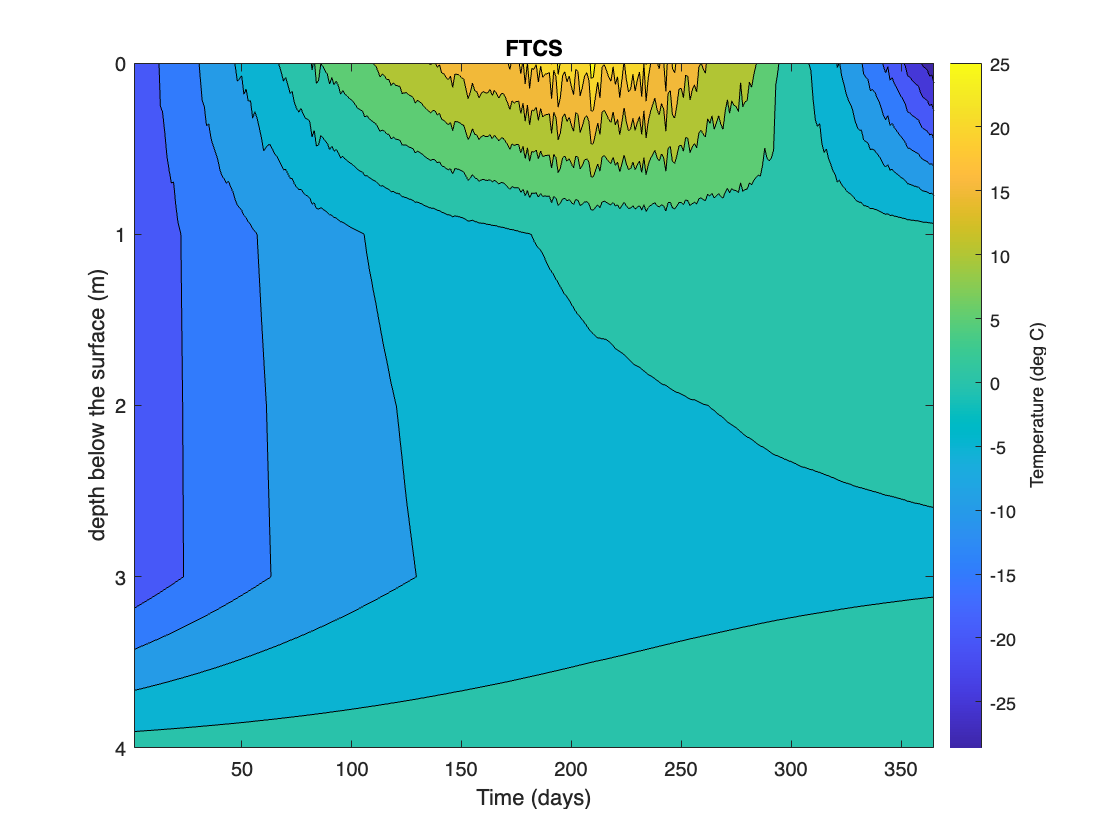

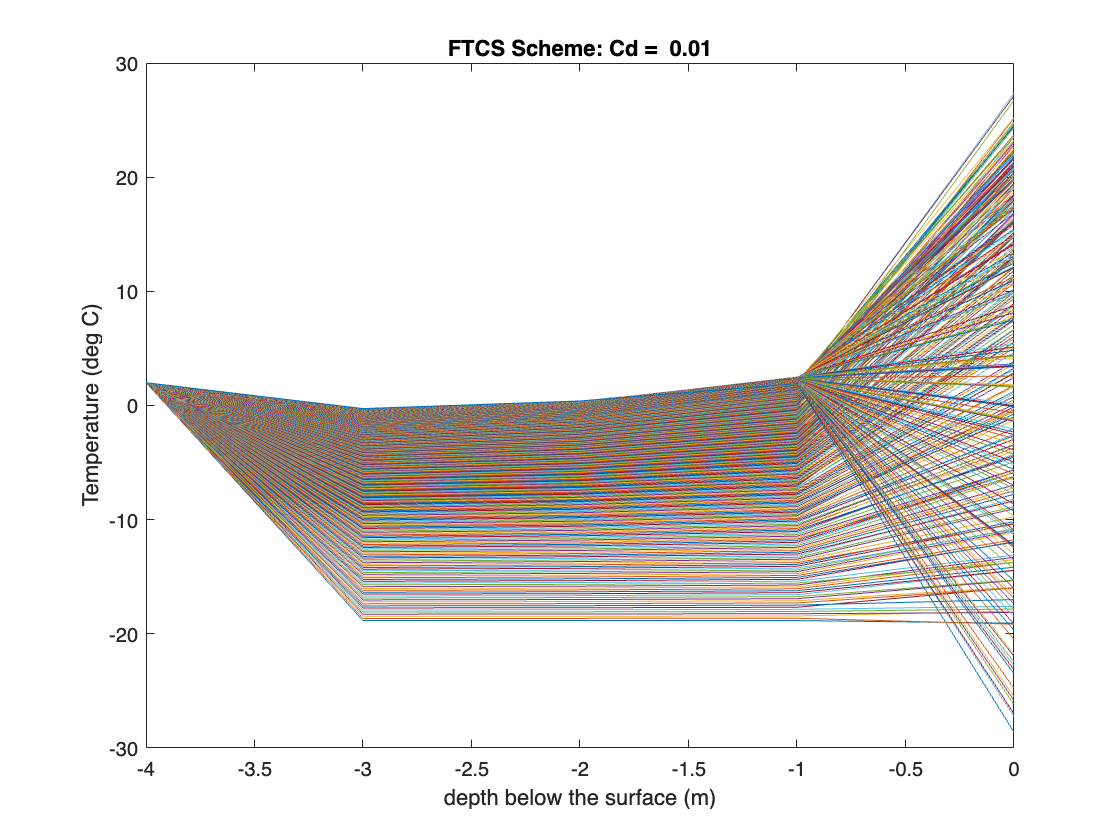

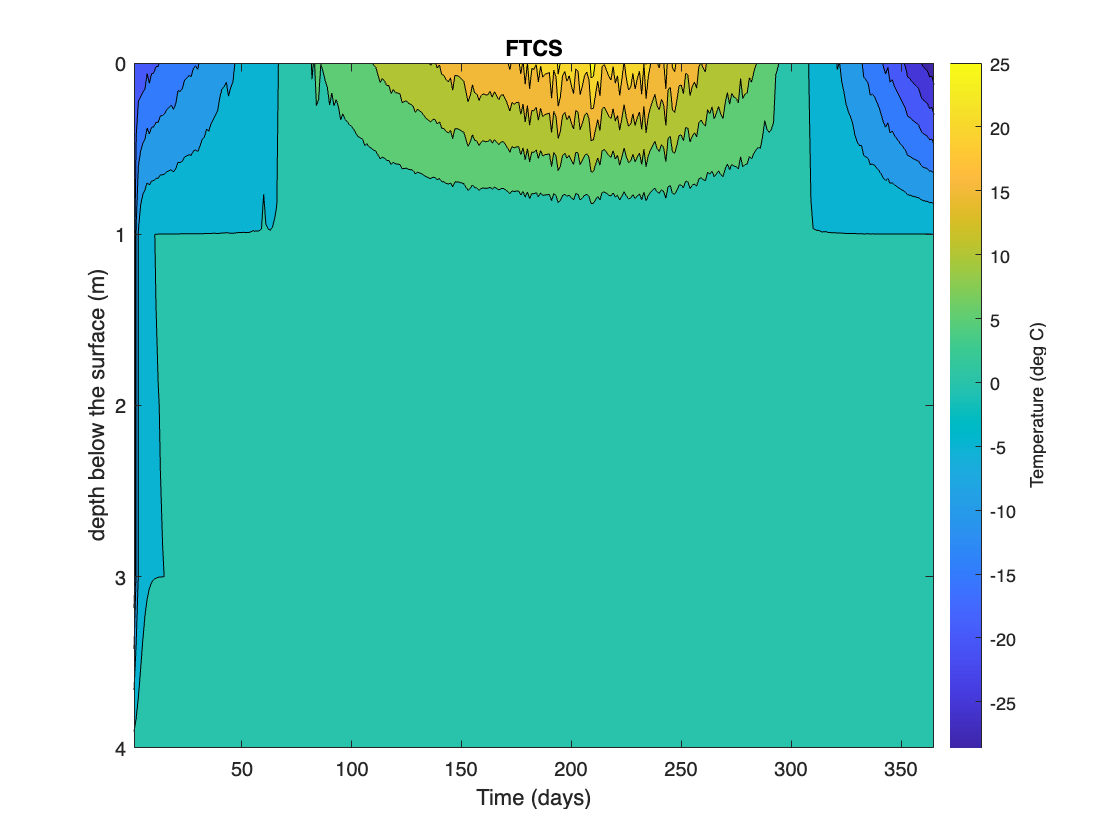

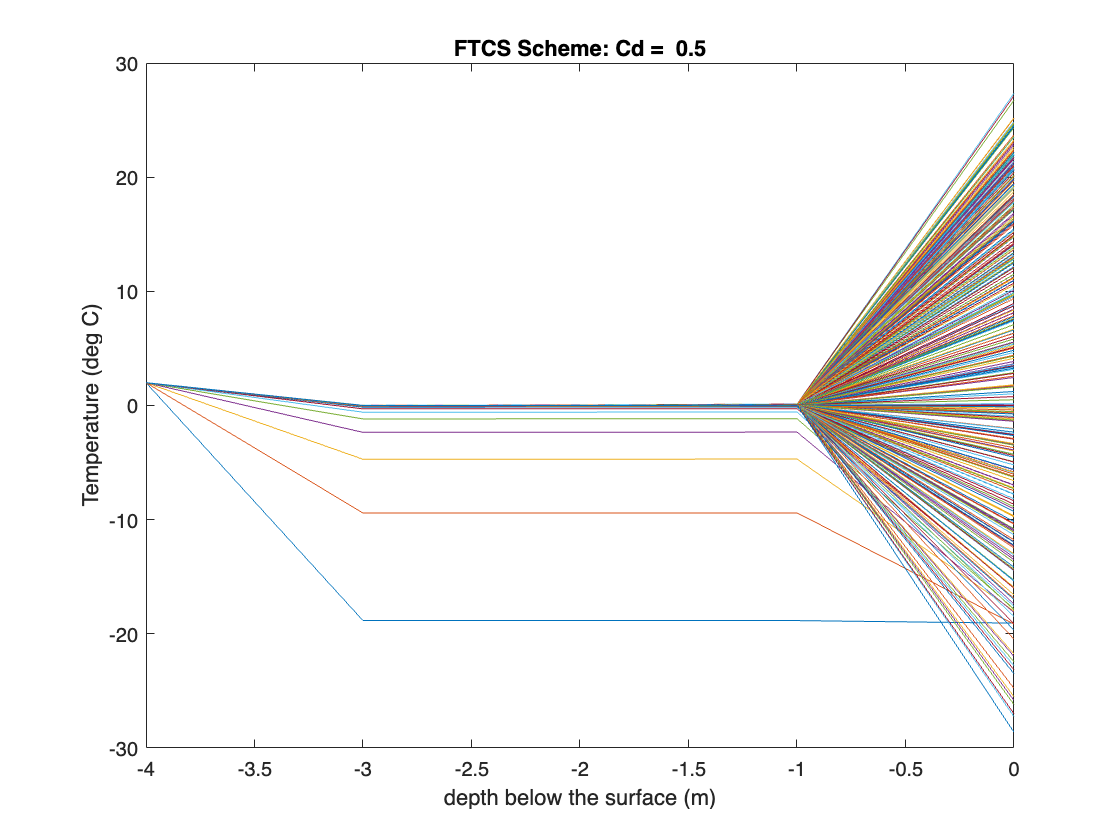

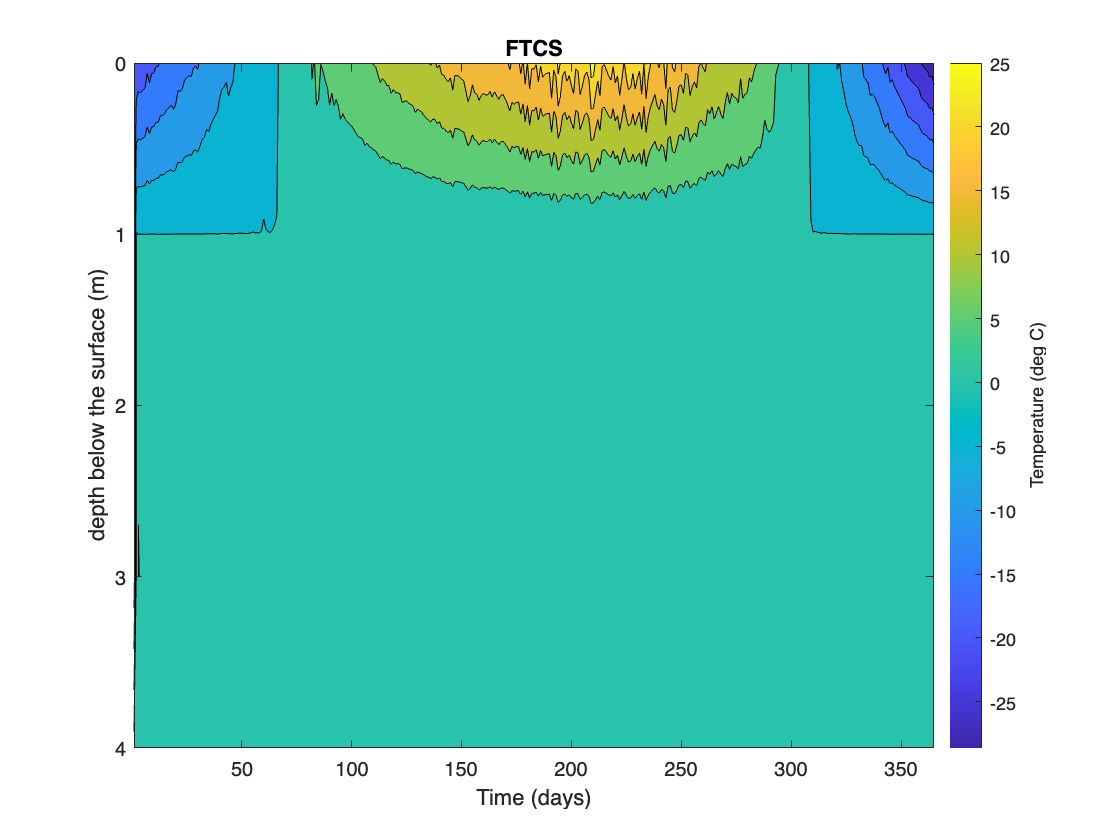

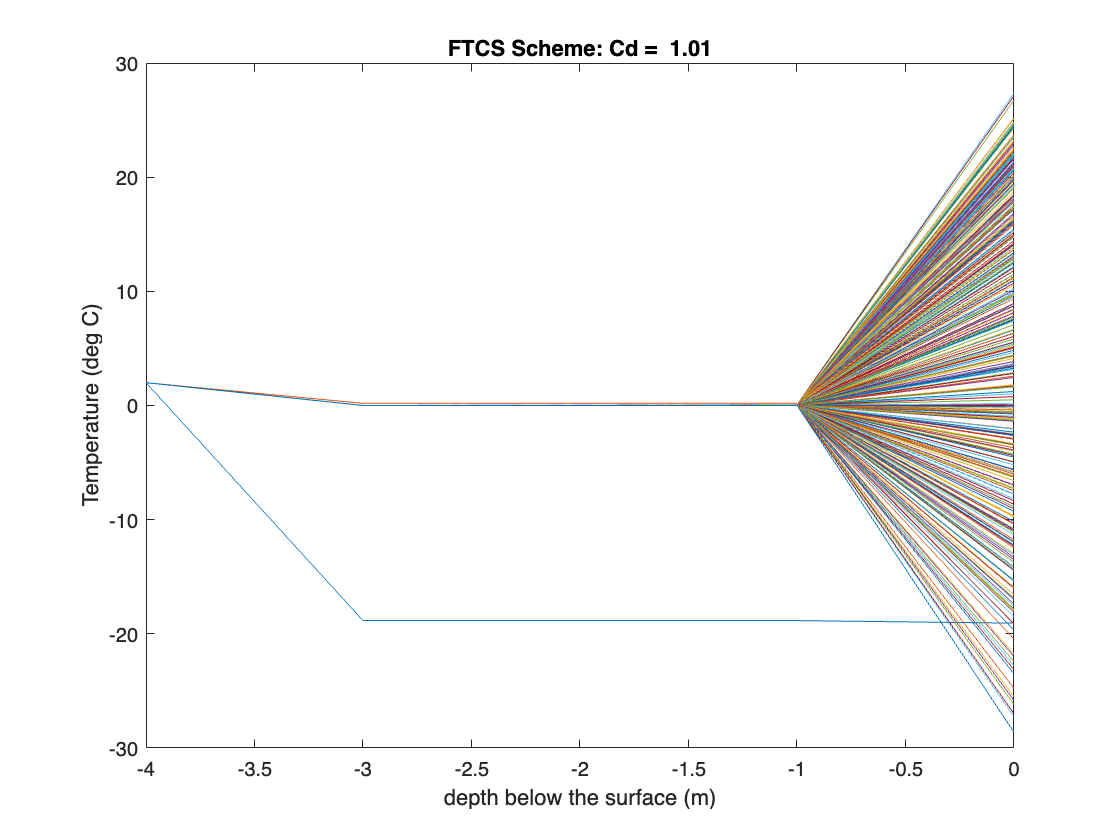

n = 1.2;
Cds = [0.01,0.5,1.01];
for y = 1:length(Cds) 
    Cd = Cds(y);
    %set "source" term 
    for i = 1: width(S)
        S(:,i)= 1./(A*Cw);
    end 
    S(1,1) = 0; 
    
    %set surface boundary condition 
    for i= 1: nt
        Tbound(1,i)=surftemp(I(i)); %neuman boundary aprroximated by cubic spline interpolation of observed data
    end 
    
    %set bottom boundary 
    Tbound(end, :)= 2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
    %set intial condition (T0 for all z)
    T(1,:)=Tbound(1,:);  
    T(end,1)= Tbound(end,1); 
    T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing
    
    for i=1:nt-1
    %dependant on U2, I, Ta, Tw,C
    
    Ts=surftemp(I(i));
    a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
    deltadeg=-23.4*cos(360*(I(i) + 10)/365);
    delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
    cos_H=-tan(theta)*tan(delta);
    H=acos(cos_H);%half-day length (units?) (14)  
    b = a + sin(theta)*sin(delta); %(17)
    c=cos(theta)*cos(delta);%(18)
    B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
    
    if ((b^2) -(c^2)) > 0 %16
        F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
    else 
        F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
    end 
    As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
    
    Tk = Ts+273;%temperature of surface in kelvin 
    rhof= (1-1.9549E-5*abs(Tk-277)^1.68)*10^3; %density of fresh water (kg/m^3)
    Nbv= 0.002;%sqrt(-g/(rhof*(dp/dp/dz)));%brunt-vaisala frequency N 
    
    tk= 1-(375.15/(Ts+273));%ambient vapor pressure of the air (27) 
    tk2= 1-(375.15/(Tw(i)+273));
    e0= 101.325*exp(13.3185*tk -1.9760*tk^2 -0.6445*tk^3 -0.1299*tk^4); % saturation vapor pressure at the lake surface 
    eas=101.325*exp(13.3185*tk2 -1.9760*tk2^2 -0.6445*tk2^3 -0.1299*tk2^4);
    gamma=(Cp*P(i))/(lambda*Rmw); %psychometric constant (kPa degC ^-1) 
    ea = eas - gamma*(Ta(i)-Tw(i)); % ambient vapor pressure of the air
    
    if (1-C(i)) > 0.4 || (1-C(i)) == 0.4
        esp_a= 0.84 - (0.1-9.973E-6*ea)*(1-C(i)) + 3.491E-5*ea; % (21) emissivity of the atmosphere
    else 
        esp_a= 0.87 -(0.175 -29.92E-6*ea)*(1-C(i)) + 2.693e-5*ea; %(22)
    end 
    %Energy Balance Parameters to solve surface BC 
    Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
    ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)
    ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
    Ld= esp_a*sig*(Ta(i) +273)^4; % (20) 
    Lds= (1-A1)*Ld; %long wave radiation from the atmosphere (23)
    Lu= esp*sig*(Ts+273)^3 ;%stefan boltzman law (24) longwave rad from lake surface 
    Le=1.91846E6*((Ts +273)/(Ts +329.09))^(2); %latent hear fo vaporization (MJ kg^-1) 
    E= N*U2(i)*(eas-ea)/1000; %evaporation (mm) -> meters 
    Qe= rhoe*Le*E; %(29) rho is density of the evaporated water vapor (= 1kg m^-3) and Le is the latent heat of vaporization (MJ kg^-1) 
    R= gamma*(Ts-Ta(i))*(e0-ea); %bowen ratio R
    Qh= R*Qe; % flux of sensible heat (31)
    
        for m=2:nz-1
            Ri= richnum(Nbv, k,ws,z(m)); %richardson number 
            K(m) = km + eddy_dif(z(m),k,ws,ks,Ri,P0);
            T(1,i)= T(1,i) + ((Ks+Lds-Lu+Qe+Qh)*1E6/(rhof*(A(m)*Cw)))/(K(m));
            phi(i)= (1-Beta)*Ks*exp(-n*z(m))*24*3600; % heat source term in (W/m^2) Beer's Law (2)
            S(m,i) = S(m,i)*phi(i)*(A(m-1)-A(m))/(dz*rhof);
            T(m,i+1) = T(m,i) + Cd*(T(m,i)-T(m-1,i)-2*T(m,i)+T(m-1,i)) + S(m,i);
            T(end,:) = T(end,1);
        end 
    end

    T_inverted = flipud(T);%invert so that the top is the surface 
    figure()
    % Create the contour plot with the inverted depth axis
    contourf(T_inverted)
    % Set the depth values as y-axis tick labels
    depth_labels = string(z);  % Assuming 'z' contains your depth values
    depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
    yticks(1:length(z))  % Set the number of ticks to match the depth values
    yticklabels(depth_labels)  % Set the depth values as tick labels
    ylabel("depth below the surface (m)")
    xlabel("Time (days)")
    cb=colorbar;
    ylabel(cb, 'Temperature (deg C)')
    title("FTCS")

    figure()
    plot(-z,T)
    title("FTCS Scheme: Cd =  " + string(Cd))
    xlabel("depth below the surface (m)")
    ylabel("Temperature (deg C)")
   
end 

**Simulation 6**

Conditions: 

    Numerical Method: Crank Nicholoson Method 

    Surface Boundary Condition: neuman boundary approximated by cubic spline interpolation of observed 2022 data

    Bottom Boundary Condition: no-flux neuman boundary, 2 degrees warmer than surface temperature on Jan. 1 2022 

    Cd = depth-dependent 

All conditions for simulation 6 followed those of simulation 2. However, this model was solved using a Crank Nicholson method. From these two simulations, it is evident that there are differences in the thermal structure that results from their implementation. Both models do show warmer temperatures throughout the water column in the fall that are a delayed response from summertime heating. It should be noted that the degree of warming in these below surface layers is more pronounced in the Crank Nicholson method. This could suggest that the Crank Nicholson method yields more detailed results.  

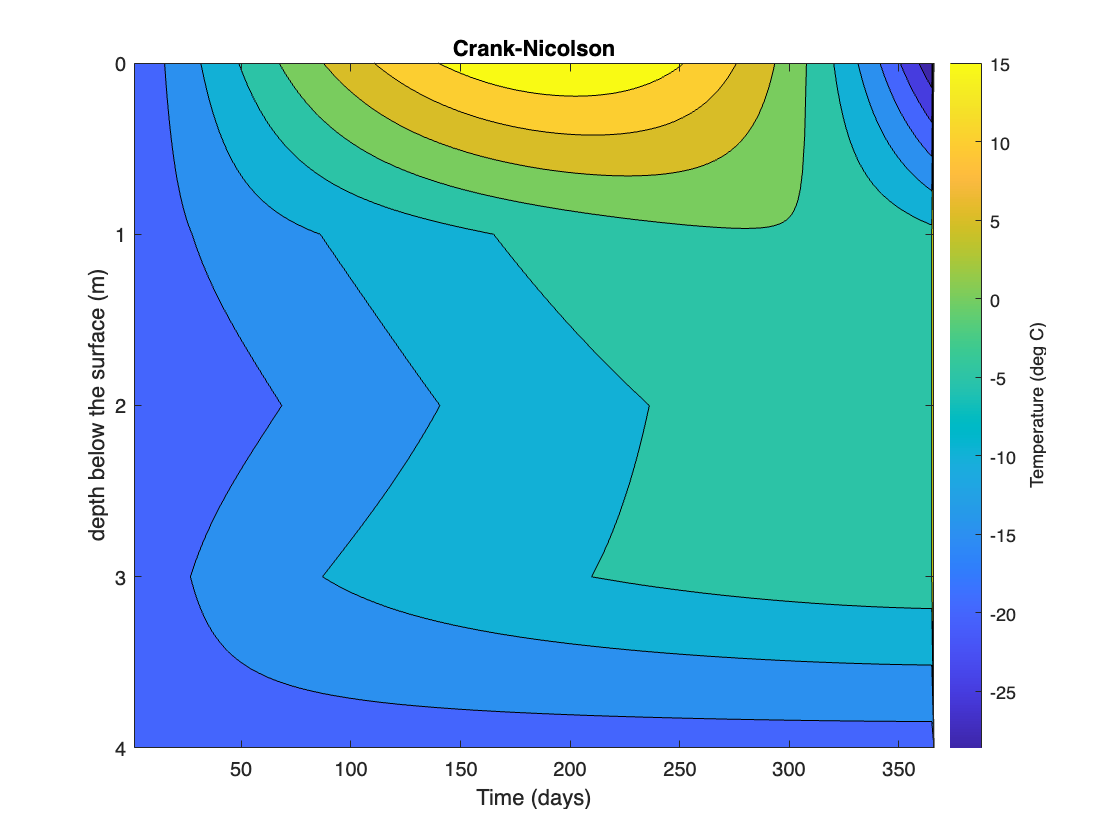

%preallocation 
I=linspace(1,365,365); % julian day 
t= I; %time in julian days 
nt= 365;
dz=1;
D=.01;
dt=1;
Cd= D*dt/dz^2; 
z=0:1:4;
nz=length(z);
T=nan.*ones(nz,nt+1);
Tbound = zeros(nz-2, nt+1);
nt=length(t);
S=nan.*ones(nz,nt);
phi = nan.*ones(1,nt);
K = nan.*ones(nz,1);
%Parameters needed to solve the equation within the Crank-Nicholson method

 
%set "source" term 
for i = 1: width(S)
    S(:,i)= 1./(A*Cw);
end 
S(1,1) = 0; 

%set surface boundary condition 
for i= 1:nt
    Tbound(1,i)=surftemp(I(i));
end 

T(1,:) = Tbound(1,:);
%set bottom boundary 
Tbound(end, :)= Tbound(1,1)+2; %sufficiently turbid such that it can be assumed to be insulated at bottom 
%set intial condition (T0 for all z)
T(1,:)=Tbound(1,:);  
T(end,1)= Tbound(end,1); 
T(2:end-1,1)= Tbound(1,1)+0.5; %assume polymicitic lake thus little mixing

%Set boundary conditions
Tbound(end,:)=-3; %deg C
% sets surface layer to be function of time for boundary and initial
% conditions

%set inital conditions for T
T(end, :)=T(1,1)+2;%z at 4 = 11 
T(2:end-1,1)=T(1,1)+0.5;%assume 10 everywhere else for t0
T;
% define M_right (MR) and M_left (ML) tridiagonal CN method
aal(1:nz-3)=-Cd/2;
bbl(1:nz-2)=1+Cd;
ccl(1:nz-3)=-Cd/2;
ML= diag(bbl,0) +diag(aal, -1) + diag(ccl,1);
aar(1:nz-3)=Cd/2;
bbr(1:nz-2)=1.-Cd;
ccr(1:nz-3)=Cd/2;
MR= diag(bbr,0) +diag(aar, -1) + diag(ccr,1);
ws= 1.2E-3*U2(i);%w* is the surface value of the friction velocity (m s-) (6)

%multiply ML inverse and MR
%implement CN

for k=1:nt
    Ts=surftemp(I(i));
    a= 0.02 + 0.01*(0.5-C(i))*(1-sin(pi*(I(i)-81)/183));%parameter that depends on cloud cover an djulian day (13)
    deltadeg=-23.4*cos(360*(I(i) + 10)/365);
    delta=deg2rad(deltadeg);%solar declination determined by Oke, 1987 (15)
    cos_H=-tan(theta)*tan(delta);
    H=acos(cos_H);%half-day length (units?) (14)  
    b = a + sin(theta)*sin(delta); %(17)
    c=cos(theta)*cos(delta);%(18)
    B= ((b-c)/(b+c))*tan(pi*H/(2*td))^2; % (19)
    if ((b^2) -(c^2)) > 0 %16
    F= 2*(b^2-c^2)^(-1/2)*atan(sqrt(B)); %integration factor 
    else 
        F= (-b+c^2)^(-1/2)*log((1+sqrt(-B)/(1-sqrt(-B))));%for b^2-c^2 <0; (16)
    end 
    As= (a*td/2*H*pi)*F;  %shortwave albedo of the water surface (12)
    Ks= Kd(i)*(1-As);%is the net shortwave radiation at the water surface (W/m^2) (11) 
    ks=  6.6*(sin(theta))^(1/2)*U2(i)^-1.84;% a  latitudinally dependent parameter of the Ekman profile, (7) 
    for j = 2:nz
        Ri= richnum(Nbv, k,ws,z(j)); %richardson number 
        K(j) = km + eddy_dif(z(j),k,ws,ks,Ri,P0);
        phi(i)= (1-Beta)*Ks*exp(-n*z(j))*24*3600; % heat source term in (W/m^2) Beer's Law (2)
        S(j,i) = S(j,i)*(phi(i)*(A(j-1)-A(j))/(dz*rhof));
        Cd = K(m)*dt/dz^2;
    end 
    T(2:nz-1, k+1) = inv(ML) * (MR*T(2:nz-1,k) + 0.5*Cd*Tbound(:,k) + 0.5*Cd*Tbound(:,k+1))+S(2:nz-1,k);
end

T_inverted = flipud(T);%invert so that the top is the surface 
figure()
% Create the contour plot with the inverted depth axis
contourf(T_inverted)
% Set the depth values as y-axis tick labels
depth_labels = string(z);  % Assuming 'z' contains your depth values
depth_labels = depth_labels(end:-1:1);  % Reverse the order to match inverted T
yticks(1:length(z))  % Set the number of ticks to match the depth values
yticklabels(depth_labels)  % Set the depth values as tick labels
ylabel("depth below the surface (m)")
xlabel("Time (days)")
cb=colorbar;
ylabel(cb, 'Temperature (deg C)')
title("Crank-Nicolson")

functions: 

function K=eddy_dif(z,k,ws,ks,Ri,P0)%(m^2*d^-1)
    K= (k*ws*z/P0)*exp(-ks*z)*(1+ 37*Ri^2)^-1; 
end 
function Ts= surftemp(I)
 Ts = -2E-06*I^3 - 0.0002*I^2 + 0.3149*I - 19.655; %cubic spline interpolation 
end 
function Ri = richnum(Nbv,k,z,ws)
    Ri= (-1 + ((1+ 40*(Nbv^2)*(k^2)*(z^2))/ ((ws^2)*exp(-2*k*z)))^(1/2))/20; %richardson number 
end 

**References**

Bartosiewicz, M., Przytulska, A., Lapierre, J.-F., Laurion, I., Lehmann, M., & Maranger, R. (2019). Hot tops, cold bottoms: Synergistic climate warming and shielding effects increase carbon burial in lakes. *Limnology and Oceanography Letters*, *4*. [https://doi.org/10.1002/lol2.10117](https://doi.org/10.1002/lol2.10117) 

Condie, S. A., & Webster, I. T. (2002). Stratification and Circulation in a Shallow Turbid Waterbody. *Environmental Fluid Mechanics*, *2*(3), 177–196. [https://doi.org/10.1023/A:1019898931829](https://doi.org/10.1023/A:1019898931829) 

Hostetler, S. W., & Bartlein, P. J. (1990). Simulation of lake evaporation with application to modeling lake level variations of Harney‐Malheur Lake, Oregon. *Water Resources Research*, *26*(10), 2603–2612. [https://doi.org/10.1029/WR026i010p02603](https://doi.org/10.1029/WR026i010p02603)

Goudsmit, G.H.; Burchard, H.; Peeters, F. Application of k-ε turbulence models to enclosed basins: The role of internal seiches. *J. Geophys. Res. Ocean.* **2002**, *107*.

Stepanenko, V.M.; Lykossov, V.N. Numerical modeling of heat and moisture transfer processes in a system lake—Soil. *J. Russ. Meteorol. Hydrol.* **2005**, *3*, 95–104.

Stepanenko, V.; Joehnk, K.D.; Machulskaya, E.; Perroud, M.; Subin, Z.; Nordbo, A.; Mammarella, I.; Mironov, D. Simulation of surface energy fluxes and stratification of a small boreal lake by a set of one-dimensional models. *Tellus* **2014**, *66*, 174–179

Wang, Y., Ma, Q., Gao, Y., Hao, X., & Liu, S. (2019). Simulation of the Surface Energy Flux and Thermal Stratification of Lake Taihu with Three 1-D Models. *Water*, *11*(5), Article 5. [https://doi.org/10.3390/w11051026](https://doi.org/10.3390/w11051026)

Yeates, P.S.; Imberger, J. Pseudo two-dimensional simulations of internal and boundary fluxes in stratified lakes and reservoirs. *Int. J. River Basin Manag.* **2003**, *1*, 297–319